1)  Analytische + numerische Näherungslösung

BWGL analytisch gelöst:


$$\[
\ddot{x} + \frac{g}{L}\,x = 0
\]

\textbf{Ansatz:}
\[
y = e^{\lambda x}, \qquad y'' = \lambda^2 e^{\lambda x}
\]

Einsetzen:
\[
e^{\lambda x}\left(\lambda^2 + \frac{g}{L}\right) = 0
\]

Charakteristische Gleichung:
\[
\lambda^2 + \frac{g}{L} = 0
\]

\[
\lambda_{1,2} = \pm i\sqrt{\frac{g}{L}}
\]

Allgemeine Lösung der DGL:
\[
y(t) = c_1 \cos\!\left(\sqrt{\frac{g}{L}}\,t\right)
      + c_2 \sin\!\left(\sqrt{\frac{g}{L}}\,t\right)
\]

Setze:
\[
\omega = \sqrt{\frac{g}{L}}
\]

\textbf{Anfangsbedingungen:}

\[
y(0) = c_1 \cos(0) + c_2 \sin(0) = c_1
\]
\[
\Rightarrow \quad c_1 = y(0) = \varphi_0
\]

\[
\dot{y}(t) = -c_1 \omega \sin(\omega t) + c_2 \omega \cos(\omega t)
\]

\[
\dot{y}(0) = c_2 \omega
\quad \Rightarrow \quad
c_2 = \frac{\dot{y}(0)}{\omega}
\]

\textbf{Pendel senkrecht ausgelenkt und aus der Ruhe losgelassen:}
\[
\varphi(0) = \varphi_0, \qquad \dot{\varphi}(0) = 0
\]

\[
\Rightarrow \quad c_2 = 0
\]

\textbf{Endlösung:}
\[
y(t) = \varphi_0 \cos(\omega t)
\]
$$



$$\textbf{Periodendauer analytisch}
\[
\[
T_0 = \frac{2\pi}{\omega}
\]

\[
\omega = \sqrt{0.1}
\]

\[
\Rightarrow \quad
T_0 = \frac{2\pi}{\omega } = 20\pi \approx 19.86
\]
$$


clear; clc; close all; % (erklärungen folgen)

g = 9.81;
l = 98.1;
omega = sqrt(g/l);  
T0 = 2*pi / omega % analytisch

T0 = 19.8692

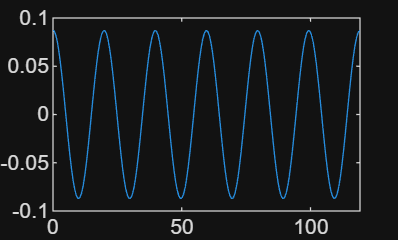

phi_0 = deg2rad(5);

[t, y] = ode45(@(t,y) fty(t,y,g,l), [0 6*T0], [phi_0; 0]);
phi = y(:,1);
plot (t, phi)

phi = y(:,1);
k = find(phi(1:end-1) < 0 & phi(2:end) >= 0);
t0 = t(k) - phi(k).*(t(k+1)-t(k))./(phi(k+1)-phi(k));
T_num = mean(diff(t0))

T_num = 19.8673


function dydt = fty(t, y, g, l)
    phi = y(1);
    phi_dydt = y(2);
    dydt= [phi_dydt;
           -(g/l)*phi];
end

%-----------Exakte numerische Lösung-----------% (erklärungen folgen)
targets = [0.01 0.05 0.10 0.50 1.00];  

for j = 1:numel(targets)
    p = targets(j);
    F = @(phi0) T_exact(phi0,g,l,T0)/T0 - (1+p);
    a = deg2rad(0.1);
    b = pi - deg2rad(0.1);
    Fa = F(a);
    Fb = F(b);
    phi0 = fzero(F, [a b]);            
    Tex = T_exact(phi0,g,l,T0);
    fprintf("%3.0f%%  = %9.4f Grad  T = %.8f s\n", 100*p, rad2deg(phi0), Tex);
end

  1%  =   22.8138 Grad  T = 20.06786830 s
  5%  =   50.1040 Grad  T = 20.86263536 s
 10%  =   69.3251 Grad  T = 21.85609418 s
 50%  =  132.6765 Grad  T = 29.80376480 s
100%  =  159.7539 Grad  T = 39.73835306 s



function T = T_exact(phi0,g,l,T0)
    y0 = [phi0; 0];
    odefun = @(t,y) [y(2); -(g/l)*sin(y(1))];
    opts = odeset('RelTol',1e-13,'AbsTol',1e-16,'Events',@event_zero_down);
    tmax = 50*T0;
    [t, y, te, ye, ie] = ode45(odefun, [0 tmax], y0, opts);
    tq = te(1);
    T  = 4*tq;
end

function [value,isterminal,direction] = event_zero_down(~,y)
    value = y(1);
    isterminal = 1;
    direction = -1;
end

%-----------Sekundenpendel-----------%
ts = 2;

%-----------Bestimmung der Parameter aus Messdaten-----------%
